% Lab 1: Cartesian trajectory planning
clearvars

P0=[1 0 0 0.3740; 0 1 0 0; 0 0 1 0.6300; 0 0 0 1];
P1=[0 0 1 0.3038; 0 1 0 0; -1 0 0 0.0510; 0 0 0 1];
P2=[0 -1 0 0; 0 0 1 0.3020; -1 0 0 0.5580; 0 0 0 1];

tau=1;
T=10;

## Exercise 1: Cartesian interpolation

[p1, q1]=qpinter(P0, P1, 0)  %% (1)!

p1 =     0.3740         0    0.6300


q1 =      1     0     0     0


[p2, q2]=qpinter(P0, P1, 1)

p2 =     0.3038         0    0.0510


q2 =     0.7071         0    0.7071         0


[p3, q3]=qpinter(P1, P2, 0)

p3 =     0.3038         0    0.0510


q3 =     0.7071         0    0.7071         0


[p4, q4]=qpinter(P1, P2, 1)

p4 =          0    0.3020    0.5580


q4 =     0.5000   -0.5000    0.5000    0.5000


q2tr(q4)

ans =     0.0000   -1.0000         0         0
         0    0.0000    1.0000         0
   -1.0000         0    0.0000         0
         0         0         0    1.0000


[p5, q5]=qpinter(P0, P2, 1)

p5 =          0    0.3020    0.5580


q5 =     0.5000   -0.5000    0.5000    0.5000


[p6, q6]=qpinter(P0, P2, 0)

p6 =     0.3740         0    0.6300


q6 =      1     0     0     0


## Exercise 2: Smooth trajectory generation

% Load ABB IRB120 model
[IRB120, IRB120Data] = loadrobot('abbIrb120','DataFormat','row','Gravity',[0 0 -9.81]);
Home=IRB120.homeConfiguration; % Use home position as start setting for inverser kinematics
% Create object for inverse kinematics
ik_IRB120 = inverseKinematics('RigidBodyTree', IRB120);
% Tolerances
weights=[0.25 0.25 0.25 1 1 1];
% Create figure to represent the manipulator
f1=figure(1)

f1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 458 560 420]
       Units: 'pixels'

  Show all properties


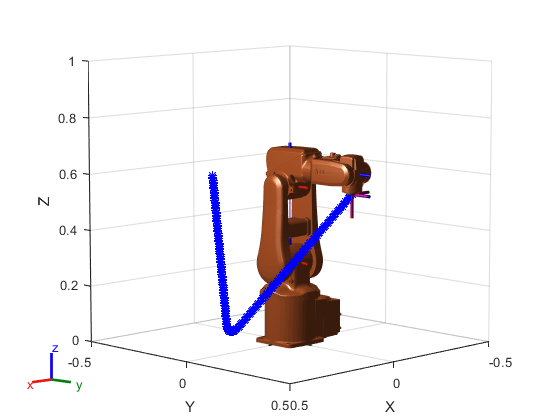

set(f1,'Name','Manipulador');

% Calculate the interpolation for the whole segment
x=[]; y=[]; z=[]; alfa=[]; beta=[]; gamma=[];
for t=-T:0.1:T
    % Call the function to generate the smoothed cartesian path
    [P,Q]=generate_smooth_path(P0,P1,P2,tau,T,t); %% (2)!
    x=[x P(1)];
    y=[y P(2)];
    z=[z P(3)];
    
    Tq=q2tr(Q);
    Tq(1:3,4)=[P(1) P(2) P(3)]'; % Complete homogeneous transofrmation matrix
    ZYZ=tr2zyz(Tq);
    
    alfa=[alfa,ZYZ(1)];
    beta=[beta,ZYZ(2)];
    gamma=[gamma,ZYZ(3)];
    
    % Get position and orientation in joint space (ik)
    [robot_pose, solnInfo]=ik_IRB120('tool0',Tq, weights, Home);
    % Represent each configuration of the robot
    ax=show(IRB120, robot_pose); axis([-0.5,0.5,-0.5,0.5,0,1]);
    hold on
    plot3(ax, x, y, z, 'b*')
    hold off
    drawnow
end

## Exercise 3: Graphical representation

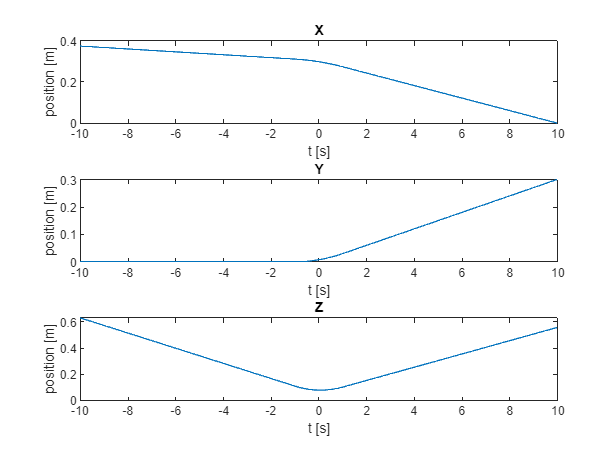

% Represent cartesian position
t=-T:0.1:T;
f2=figure(2);
set(f2,'Name','Cartesian position');
subplot(3,1,1),plot(t,x);title('X');xlabel('t [s]'); ylabel('position [m]');

subplot(3,1,2),plot(t,y);title('Y');xlabel('t [s]'); ylabel('position [m]');
subplot(3,1,3),plot(t,z);title('Z');xlabel('t [s]'); ylabel('position [m]');

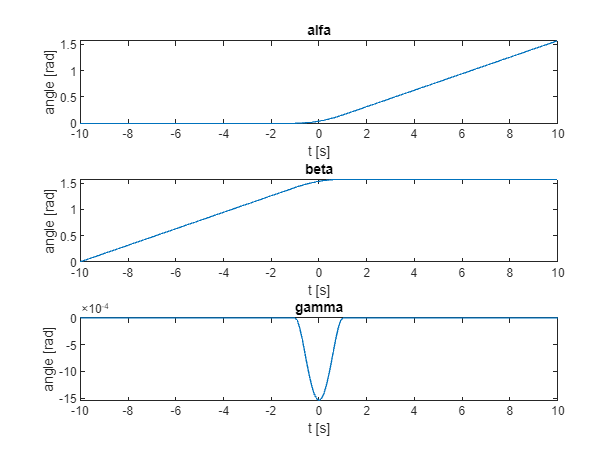


% Represent cartesian orientation as Euler angles
f3=figure(3);
set(f3,'Name','Ángulos de Euler');
subplot(3,1,1),plot(t,alfa);title('alfa');xlabel('t [s]'); ylabel('angle [rad]');
subplot(3,1,2),plot(t,beta);title('beta');xlabel('t [s]'); ylabel('angle [rad]');
subplot(3,1,3),plot(t,gamma);title('gamma');xlabel('t [s]'); ylabel('angle [rad]');

function [p,q]=qpinter(P0, P1, lamba)
%Transformar P0 a quaternio
q0=tr2q(P0);
q1=tr2q(P1);

qc=qqmul(qinv(q0),q1);
theta=2*acos(qc(1,1));
n=[qc(1,2),qc(1,3),qc(1,4)]/sin(theta/2);

w_rot=cos(theta*lamba/2);
v_rot=n*sin(theta*lamba/2);
q_rot=[w_rot,v_rot];
q=qqmul(q0,q_rot);


%Traslación
p_lamba=[P0(1,4),P0(2,4),P0(3,4)]+lamba*([P1(1,4),P1(2,4),P1(3,4)]-[P0(1,4),P0(2,4),P0(3,4)]);
%solución traslación
p=p_lamba;

end

function [P, Q]=generate_smooth_path(P1, P2, P3, tau, T, t)
    % Function that calculates the transformation (P - position, and Q - orientation) from P1 to P3 smoothing in P2 with Taylor method (quaternions)
    

    if (t<-T || t>T)
        % Out of allowed range
        disp('Parameter t out of range');
    else

        if (t<=-tau) % First segment (lineal)
            [P,Q]=qpinter(P1,P2,(t+T)/T);
            
        elseif (t>=tau) % Third segment (lineal)
            [P,Q]=qpinter(P2,P3,t/T);
        else % Second segment (smoothing)
            p1=[P1(1,4);P1(2,4);P1(3,4)];
            p2=[P2(1,4);P2(2,4);P2(3,4)];
            p3=[P3(1,4);P3(2,4);P3(3,4)];
            % Position interpolation
            P=p2 - ((((tau-t)^2)/(4*tau*T))*(p2-p1)) + ((((tau+t)^2)/(4*tau*T))*(p3-p2));
            q1=tr2q(P1);
            q2=tr2q(P2);
            q3=tr2q(P3);
            %12
            q12=qqmul(qinv(q1),q2);
            theta12=2*acos(q12(1,1));
            n12=[q12(1,2),q12(1,3),q12(1,4)]/sin(theta12/2);
            %23
            q23=qqmul(qinv(q2),q3);
            theta23=2*acos(q23(1,1));
            n23=[q23(1,2),q23(1,3),q23(1,4)]/sin(theta23/2);

            %Ángulos
            thetak1=(-(tau-t)^2)*theta12/(4*tau*T);
            thetak2=((tau+t)^2)*theta23/(4*tau*T);

            %Quaternios
            qk1=[cos(thetak1/2), n12*sin(thetak1/2)];
            qk2=[cos(thetak2/2), n23*sin(thetak2/2)];





            %Transformar P0 a quaternio

            Q=qqmul(qqmul(q2,qk1),qk2);


            % Orientation interpolation
            
        end

    end
end


function q=tr2q(T,m)

if nargin==1, m=1; end
M=sign(m);
S=M*sqrt(T(1,1)+T(2,2)+T(3,3)+1)/2;
if abs(S)>1e-3
	X=(T(3,2)-T(2,3))/4/S;
	Y=(T(1,3)-T(3,1))/4/S;
	Z=(T(2,1)-T(1,2))/4/S;
else
	S=0;
	X=M*sqrt((T(1,1)+1)/2);
	Y=M*sqrt((T(2,2)+1)/2);
	Z=M*sqrt((T(3,3)+1)/2);
end
q=[S,X,Y,Z];
end
function q2=qinv(q)

q2=[q(1)/(sqrt(q(1)^2+q(2)^2+q(3)^2+q(4)^2)),-q(2:4)/(sqrt(q(1)^2+q(2)^2+q(3)^2+q(4)^2))];
end
function q=qqmul(q1,q2)

q=[q1(1)*q2(1)-q1(2:4)*q2(2:4)',q2(1)*q1(2:4)+q1(1)*q2(2:4)+cross(q1(2:4),q2(2:4))];
end